% Set up
clc;
close all;
clear;

## Read data from edf and xml files

% Initialize with 10 x 1 cell array
EEG1 = cell(10,1); % channel 3, Fs = 125
EEG2 = cell(10,1); % use EEG2{1} to visit the first matrix
EOGL = cell(10,1); % channel 6, Fs = 50
EOGR = cell(10,1);
EMG0 = cell(10,1); % channel 5, Fs = 125
STAGE = cell(10,1);


% load all data
for n = 1:10
    edfFilename = sprintf('R%d_edf.mat', n);
    xmlFilename = sprintf('R%d_xml.mat', n);
    load(edfFilename);
    load(xmlFilename);
    Fs = hdr.samples(3); % Since this is the biggest Frequency (125 Hz), we use it to calculate number of epochs
    Fs_EOG = hdr.samples(6);
    % every epoch lasts for epochLength seconds (30 seconds)
    numberOfEpochs = length(record(3,:)')/(Fs*epochLength)-1;   % cut the last epoch
    samplingPoints_EOG = numberOfEpochs*epochLength*Fs_EOG;
    % Initialization of eeg1 and eeg2
    eeg1 = zeros(numberOfEpochs,Fs*epochLength);    % epochLength = 30
    eeg2 = zeros(numberOfEpochs,Fs*epochLength);
    eogl = zeros(numberOfEpochs,Fs_EOG*epochLength);
    eogr = zeros(numberOfEpochs,Fs_EOG*epochLength);
    emg = zeros(numberOfEpochs,Fs*epochLength);
    epochAmount = 1;    % How much epoches to cut for one row
    % Fs = 125
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs*epochLength);
        eeg1(i,:) = record(8,epochStart:epochEnd);
        eeg2(i,:) = record(3,epochStart:epochEnd);
        emg(i,:) = record(5,epochStart:epochEnd);
    end
    % Fs = 50
    for i = 1:numberOfEpochs
        epochNumber = i;    % start epoch No.
        epochStart = epochNumber*Fs_EOG*epochLength;    % will cut the first epoch
        epochEnd = epochStart + epochAmount*Fs_EOG*epochLength - 1; % not include the end index
        t = linspace(0,epochAmount*30,epochAmount*Fs_EOG*epochLength);
        eogl(i,:) = record(6, epochStart:epochEnd);
        eogr(i,:) = record(7, epochStart:epochEnd);
    end
    EEG1{n} = eeg1;
    EEG2{n} = eeg2;
    EOGL{n} = eogl;
    EOGR{n} = eogr;
    EMG0{n} = emg;
    % process the stages
    stages_epoch = zeros(numberOfEpochs,1);
    for i = 1:numberOfEpochs
        stages_epoch(i) = stages(i*30);
    end
    STAGE{n} = stages_epoch;
    STAGE{n}(STAGE{n} == 1) = 2;
end

## Preprocessing & feature extraction

% The functions will filter the signals by row
% EEG
EEG1_filtered = baseline_drift_removal(EEG1,Fs,0.5);
EEG2_filtered = baseline_drift_removal(EEG2,Fs,0.5);

EEG1_filtered = muscle_noise_filtering(EEG1_filtered,Fs,30);
EEG2_filtered = muscle_noise_filtering(EEG2_filtered,Fs,30);

% EOG
[EOGL_filtered, EOGR_filtered] = preprocess_eog(EOGL, EOGR, Fs);

% EMG
[EMG_filtered, EMG_envelope] = preprocess_emg(EMG0, Fs);

% Feature Extraction
% EEG features
features_time_eeg1 = extract_time_features(EEG1_filtered);
features_time_eeg2 = extract_time_features(EEG2_filtered);

[features_freq_eeg1, Pxx_eeg1, freqs_eeg1] = extract_freq_features(EEG1_filtered, Fs);
[features_freq_eeg2, Pxx_eeg2, freqs_eeg2] = extract_freq_features(EEG2_filtered, Fs);

% Extract time-frequency features
features_timefreq_eeg1 = extract_timefreq_features(EEG1_filtered, Fs);
features_timefreq_eeg2 = extract_timefreq_features(EEG2_filtered, Fs);

% EOG features
features_EOGL=extract_EOG_features(EOGL_filtered);
features_EOGR=extract_EOG_features(EOGR_filtered);

% EMG features
features_EMG = extract_EMG_features(EMG_filtered, EMG_envelope, Fs);

% Combine features together
features = cell(size(features_timefreq_eeg2));
for i = 1:10
    features{i} = [features_time_eeg1{i}, features_time_eeg2{i},...
                   features_freq_eeg1{i}, features_freq_eeg2{i},...
                   features_timefreq_eeg1{i},features_timefreq_eeg2{i},...
                   features_EOGL{i}, features_EOGR{i},...
                   features_EMG{i}];
    % features{i} = normalize(features{i});
end

## If you have the feature data, you can skip all the steps above

% load("features_EEG+EOG+EMG.mat")

## Feature Selection

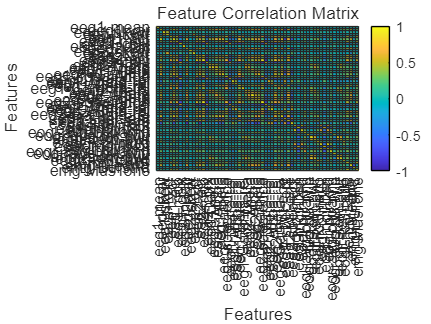

featureNames = { ...
    'eeg1-mean','eeg1-var','eeg1-skew','eeg1-kurt','eeg1-zcr', ...
    'eeg1-act','eeg1-mob','eeg1-cplx', ...
    'eeg2-mean','eeg2-var','eeg2-skew','eeg2-kurt','eeg2-zcr', ...
    'eeg2-act','eeg2-mob','eeg2-cplx', ...
    'eeg1-Delta','eeg1-Theta','eeg1-Alpha','eeg1-Beta','eeg1-Gamma','eeg1-spec-edge', ...
    'eeg1-Delta-rel','eeg1-Theta-rel','eeg1-Alpha-rel','eeg1-Beta-rel','eeg1-Gamma-rel', ...
    'eeg2-Delta','eeg2-Theta','eeg2-Alpha','eeg2-Beta','eeg2-Gamma','eeg2-spec-edge', ...
    'eeg2-Delta-rel','eeg2-Theta-rel','eeg2-Alpha-rel','eeg2-Beta-rel','eeg2-Gamma-rel', ...
    'eeg1-wlt-ene','eeg1-spec-ent', ...
    'eeg2-wlt-ene','eeg2-spec-ent', ...
    'eogl-blinkCt','eogl-movDen','eogl-blinkRt', ...
    'eogl-avg-blk-amp','eogl-avg-blk-wid','eogl-slow-pwr','eogl-rem-pwr','eogl-R/S-ratio', ...
    'eogr-blinkCt','eogr-movDen','eogr-blinkRt', ...
    'eogr-avg-blk-amp','eogr-avg-blk-wid','eogr-slow-pwr','eogr-rem-pwr','eogr-R/S-ratio', ...
    'emg-RMS','emg-MeanF','emg-BurstRt','emg-MusTone' ...
};

R = corrcoef(vertcat(features{:}));  
figure;
h = heatmap(featureNames, featureNames, R, ...
            'Colormap', parula, ...
            'ColorLimits', [-1 1]);
h.Title = 'Feature Correlation Matrix';
h.XLabel = 'Features';
h.YLabel = 'Features';

## Classification

Random Forest

%% --- Initialization -------------------------------------------------
numSubjects      = length(features);
accuracies       = zeros(numSubjects, 1);
all_predictions  = [];
all_true_labels  = [];

% Specify the feature columns to exclude
excludeIdx = [];

% RF hyper-parameters
nTrees = 50;
origD  = size(features{1}, 2);
D      = origD - numel(excludeIdx);
mtry   = ceil(sqrt(D));

% Prepare a log file
logFile   = 'rf_loso_log.txt';
timestamp = datestr(now, 'yyyy-mm-dd HH:MM:SS');

%% --- LOSO + Random Forest -------------------------------------------
for i = 1:numSubjects
    % 1) Prepare test set
    test_features = features{i};
    test_labels   = STAGE{i};
    
    % 2) Prepare training set
    train_indices  = setdiff(1:numSubjects, i);
    train_features = [];
    train_labels   = [];
    for j = train_indices
        train_features = [train_features; features{j}];
        train_labels   = [train_labels;   STAGE{j}];
    end
    
    % 3) Exclude specified features
    train_features(:, excludeIdx) = [];
    test_features(:,  excludeIdx) = [];
    
    % 4) (Optional) Normalize features
    % mu    = mean(train_features);
    % sigma = std(train_features);
    % train_features = (train_features - mu) ./ sigma;
    % test_features  = (test_features  - mu) ./ sigma;
    
    % 5) Train forest
    train_labels = categorical(train_labels);
    forest = TreeBagger( ...
        nTrees, ...
        train_features, ...
        train_labels, ...
        'Method',              'classification', ...
        'NumPredictorsToSample', mtry, ...
        'OOBPrediction',       'Off' ...
    );
    
    % 6) Predict
    [pred_cell, ~] = predict(forest, test_features);
    predictions    = categorical(pred_cell);
    
    % 7) Compute accuracy
    correct       = sum(predictions == categorical(test_labels));
    accuracies(i) = correct / numel(test_labels);
    
    % 8) Collect results
    all_predictions = [all_predictions; predictions];
    all_true_labels = [all_true_labels; test_labels];
    
    fprintf('Subject %d LOSO accuracy: %.2f%%\n', i, accuracies(i)*100);
end

Subject 1 LOSO accuracy: 85.50%
Subject 2 LOSO accuracy: 87.57%
Subject 3 LOSO accuracy: 89.12%
Subject 4 LOSO accuracy: 76.77%
Subject 5 LOSO accuracy: 88.83%
Subject 6 LOSO accuracy: 68.70%
Subject 7 LOSO accuracy: 78.65%
Subject 8 LOSO accuracy: 83.82%
Subject 9 LOSO accuracy: 75.48%
Subject 10 LOSO accuracy: 80.52%



% 9) Final metrics
overall_acc = mean(accuracies);
conf_mat    = confusionmat(categorical(all_true_labels), all_predictions);

fprintf('\nOverall LOSO accuracy: %.2f%%\n', overall_acc*100);


Overall LOSO accuracy: 81.50%


disp('Confusion Matrix:'), disp(conf_mat);

Confusion Matrix:
         693           5         264          14         142
           2        1362         247           0           7
         165         255        3188          29         171
          51           2         126           9          87
         106           1         191          31        3145




%% --- Append to Log File ---------------------------------------------
fileID = fopen(logFile, 'a');
if fileID == -1
    error('Cannot open log file %s for writing.', logFile);
end

fprintf(fileID, '\n=== Run at %s ===\n', timestamp);
fprintf(fileID, 'Excluded features: [%s]\n', num2str(excludeIdx));
fprintf(fileID, 'Hyperparameters: nTrees = %d, mtry = %d\n', nTrees, mtry);
fprintf(fileID, 'Per-subject accuracies: [%s]\n', num2str(accuracies', ' %.4f'));
fprintf(fileID, 'Overall accuracy: %.4f\n', overall_acc);
fprintf(fileID, 'Confusion Matrix:\n');
for r = 1:size(conf_mat, 1)
    fprintf(fileID, '%s\n', num2str(conf_mat(r, :), '%d '));
end

fclose(fileID);

overall_acc = mean(accuracies);
fprintf('\nOverall LOSO accuracy: %.2f%%\n', overall_acc*100);


Overall LOSO accuracy: 81.50%


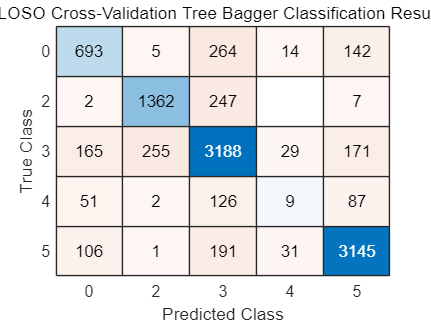

% Compute confusion matrix
cm = confusionchart(categorical(all_true_labels), all_predictions);
cm.Title = 'LOSO Cross-Validation Tree Bagger Classification Results';
cm.XLabel = 'Predicted Class';
cm.YLabel = 'True Class';

% % kNN
% numSubjects = length(features);
% accuracies = zeros(numSubjects, 1); % Accuracy for each fold
% all_predictions = []; % Prediction results
% all_true_labels = []; % Ground truth
% 
% % LOSO (Leave-One-Subject-Out)
% for i = 1:numSubjects
%     % Use the i-th subject's data as the test set
%     test_features = features{i};
%     test_label = STAGE{i};
%     
%     % Use the remaining subjects' data as the training set
%     train_indices = setdiff(1:numSubjects, i);
%     
%     % Merge training features
%     train_features = [];
%     train_labels = [];
%     
%     for j = train_indices
%         train_features = [train_features; features{j}];
%         train_labels = [train_labels; STAGE{j}];
%     end
%     
%     % Optional: Feature normalization
%     % Normalize using the mean and standard deviation from the training set
%     mean_train = mean(train_features);
%     std_train = std(train_features);
%     train_features = (train_features - mean_train) ./ std_train;
%     test_features = (test_features - mean_train) ./ std_train;
%     
%     % Train kNN model
%     knn_model = fitcknn(train_features, train_labels, 'NumNeighbors', 3, 'Distance', 'euclidean');
%     
%     % Predict test set
%     predictions = predict(knn_model, test_features);
%     
%     % Calculate accuracy
%     correct = sum(predictions == test_label);
%     total = length(test_label);
%     accuracies(i) = correct / total;
%     
%     % Store prediction results
%     all_predictions = [all_predictions; predictions];
%     all_true_labels = [all_true_labels; test_label];
%     
%     fprintf('Accuracy with subject %d as test set: %.2f%%\n', i, accuracies(i) * 100);
% end

Accuracy with subject 1 as test set: 80.70%
Accuracy with subject 2 as test set: 89.42%
Accuracy with subject 3 as test set: 83.97%
Accuracy with subject 4 as test set: 68.31%
Accuracy with subject 5 as test set: 81.90%
Accuracy with subject 6 as test set: 52.08%
Accuracy with subject 7 as test set: 64.60%
Accuracy with subject 8 as test set: 69.42%
Accuracy with subject 9 as test set: 70.32%
Accuracy with subject 10 as test set: 77.38%


% 
% %% 3. Calculate overall performance metrics
% overall_accuracy = mean(accuracies);
% fprintf('Average accuracy of LOSO cross-validation: %.2f%%\n', overall_accuracy * 100);

Average accuracy of LOSO cross-validation: 73.81%


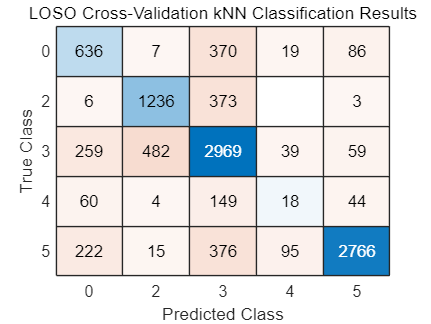

% 
% % Compute confusion matrix
% cm = confusionchart(all_true_labels, all_predictions);
% cm.Title = 'LOSO Cross-Validation kNN Classification Results';
% cm.XLabel = 'Predicted Class';
% cm.YLabel = 'True Class';